# **最优化课程设计:"LIME论文复现 "**

**代码环境:"R7000P 2020,Windows 11,MATLAB 2023a"**

## **参考文献**

%[1]是基础参考论文,[2]比较高级,还没看,[3]是全部代码和思路的主要参考文献,[4]为[3]提供了补充.

**[1] X. Guo, Y. Li, and H. Ling, “LIME: Low-light image enhancement via illumination map estimation,” IEEE Trans. Image Process., vol. 26, no. 2, pp. 982–993, Feb. 2017.**

**[2] X. Ren, W. Yang, W. -H. Cheng and J. Liu, "LR3M: Robust Low-Light Enhancement via Low-Rank Regularized Retinex Model," in IEEE Transactions on Image Processing, vol. 29, pp. 5862-5876, 2020.**

**[3] Bhavya Vasudeva, Puneesh Deora, "Report:Low-light Image Enhancement".**

**[4] Dongwei Ren, Hongzhi Zhang, David Zhang, Wangmeng Zuo, "Fast total-variation based image restoration based on derivative alternated direction optimization methods," Neurocomputing, Volume 170, 2015,Pages 201-212.**

## 第1部分 初始化

    首先,读取测试图片.MATLAB自带的"imshow"函数用于展示图片.

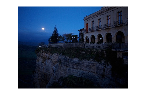

clear;
img = imread('moon.png');
imshow(img);

将图像双精度化.(我不知道这是为什么.不过,这和全文的主线内容无关,只不过是代码层面的细节)

img = im2double(img);
%img=adjustImage(img,0.5);
%imshow(img);

### 1.1 光照模型的公式

    用到的理论公式是


$$\mathbf{L}=\mathbf{R}\circ \mathbf{T},$$


其中$\mathbf{L}$是拍摄图片,而$\mathbf{R}$是希望恢复的图像,$\mathbf{T}$是照明图.注意,这里的$\circ$符号表示逐元素的乘法,用图像处理的术语来说,是所谓的逐像素点增强.在MATLAB的代码实现里,表现为需要使用$"\ldotp *"$而并非$"*"$.

    参数$\mathbf{L}$是已知的,问题在于如何获得合理的$\mathbf{T}$值以便恢复图像.

### 1.2 初始照明的估计

    由于方法论部分是使用最优化方法得到最优参数$T$,因此首先要解决的问题是选定$T$的初值$\hat{\mathbf{T}}$.

    这里选定$\textrm{RGB}$三通道的极值作为初值使用,理由来自所谓的"非均匀光照提升".数学上,可以写作


$$\hat{\mathbf{T}}(x) \leftarrow \max _{c \in\{R, G, B\}} \mathbf{L}^{c}(x),$$


其中$x$是像素点.

    使用自定义的"myLighting"函数获取初始照明图"testImg",函数具体定义则位于实时脚本文件的底部.之后类似的以"my"开头的函数均是自定义的,不再说明.其中"ini_map"是二维矩阵,其等同于"testImg"的灰色图像,理由则是所谓的"三通道共享光照",也就是默认照明图像$\mathbf{T}$的RGB三通道数值相同.这种理论确实有好处,因为如此一来便无需处理三维的彩色图像矩阵,而只需考虑二维的照明矩阵.

[testImg,ini_map] = myLighting(img);
%imshow(testImg);

### 1.3 DEMO NOW

这里给出初步的结果测试.

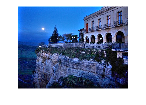

alpha=0.66;
mu0=0.4;
rho=1.1;
[T] = myTrial(ini_map, alpha, mu0, rho); 
%R=repmat(T,[1,1,3]);
newT=gammaResult(T,0.6);
newT=repmat(newT,[1,1,3]);
newR=img./newT;
imshow(newR);

PSNRval=psnr(newT(:,:,1),T);
[ssimval, ~] = ssim(newT(:,:,1), T);
disp([PSNRval,ssimval]);

   16.0420    0.8079



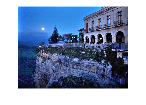

R2=adjustImage(newR,0.9);
imshow(R2);

%{
demo1=imread('building.bmp');
demo2=imread('cars.bmp');
[I1]=quickDemo(demo1, alpha, mu0, rho);
[I2]=quickDemo(demo2, alpha, mu0, rho);
%}

function outImage=quickDemo(newimg, alpha, mu0, rho)
    newimg = im2double(newimg);
    [~,ini_map] = myLighting(newimg);
    [T] = myTrial(ini_map, alpha, mu0, rho);
    newT=gammaResult(T,0.8);
    newT=repmat(newT,[1,1,3]);
    outImage=newimg./newT;
    imshow(outImage);
end
function outImage = adjustImage(inImage, k1)
    % 将输入的RGB图像转换为HSV图像
    hsvImage = rgb2hsv(inImage);
    % 降低饱和度
    hsvImage(:, :, 2) = hsvImage(:, :, 2) * k1;
    % 将HSV图像转回RGB图像
    outImage = hsv2rgb(hsvImage);
end

## 第2部分 最优化参数

   在上一部分从图像$\mathbf{L}$中抽离出核心关键照明矩阵$\mathbf{T}$后,这一部分的基本问题是

$\min _{\mathbf{T}}\|\hat{\mathbf{T}}-\mathbf{T}\|_{F}^{2}+\alpha\|\mathbf{W} \circ \nabla \mathbf{T}\|_{1}$.

其中$$\alpha$$是预先指定的平衡系数,而$\mathbf{W}$则是预先设置的权重矩阵.看起来,这是经典的LASSO问题.

    将上式调整为等价的优化问题

$\min _{\mathbf{T}, \mathbf{G}}\|\hat{\mathbf{T}}-\mathbf{T}\|_{F}^{2}+\alpha\|\mathbf{W} \circ \mathbf{G}\|_{1} \quad \text { s.t. } \quad \nabla \mathbf{T}=\mathbf{G}$.

在此式中使用增广乘子方法,最终导出以下优化问题:

$\underset{\mathbf{T},\mathbf{G}}{\mathrm{argmin}}\min_{\mathbf{Z}}\mathcal{L}(\mathbf{T},\mathbf{G};\mathbf{Z}):=\|\hat{\mathbf{T}}-\mathbf{T}\|_{F}^{2}+\alpha\|\mathbf{W} \circ \mathbf{G}\|_{1}+\Phi(\mathbf{Z}, \nabla \mathbf{T}-\mathbf{G})$,

其中$\displaystyle \Phi(\mathbf{Z}, \nabla \mathbf{T}-\mathbf{G})=\frac{\mu}{2}\|\nabla \mathbf{T}-\mathbf{G}\|_{F}^{2}+\langle\mathbf{Z}, \nabla \mathbf{T}-\mathbf{G}\rangle$,这里$$\langle\cdot, \cdot\rangle$$表示矩阵内积,$$\mu$$是一个正的惩罚标量,$\mathbf{Z}=\mathbf{Z}(\mathbf{T},\mathbf{G})$是乘子变量.

    现在要求解$\min    \mathcal{L}$,就要获得$\arg\min\mathcal{L}$对应的三个最优参数$\mathbf{T}, \mathbf{G},\mathbf{Z}$.即将使用的求解器是交替方向乘子法,也就是将最优问题关于$\mathbf{T},\mathbf{G}$分步优化.至于$\mathbf{Z}$,将会在前两个参数分步优化时一并迭代更新.

### 2.1 $\mathbf{T}$子问题

    首先需要确定$\mathbf{T}$参数是如何迭代的.这是因为$\mathbf{G}$参数的迭代需要用到$\mathbf{T}$参数迭代后的数值.

#### 2.1.1 公式的导出

    收集涉及$\mathbf{T}$的项,可以得到以下问题:


$$\mathbf{T}^{(t+1)} \leftarrow \underset{\mathbf{T}}{\mathrm{argmin}}\|\hat{\mathbf{T}}-\mathbf{T}\|_{F}^{2}+\Phi\left(\mathbf{Z}^{(t)}, \nabla \mathbf{T}-\mathbf{G}^{(t)}\right) .$$


这是一个经典的最小二乘问题,通过对$\mathbf{T}$求导来计算解.求导的结果是


$$2(\mathbf{T}-\hat{\mathbf{T}})+\mu^{(t)} \mathbf{D}^{T}\left(\mathbf{D} \mathbf{T}-\mathbf{G}^{(t)}\right)+\mathbf{D}^{T} \mathbf{Z}^{(t)}=0,$$


当然,按照此前说明的,这里$ \nabla \mathbf{T}=\mathbf{DT}$.以及,矩阵$\mathbf{D}=\left\lbrack \begin{array}{c}
{\mathbf{D}}_h \\
{\mathbf{D}}_v 
\end{array}\right\rbrack$包含$\mathbf{D}_{h}$和$\mathbf{D}_{v}$,是离散的梯度近似矩阵,具体地说,是两个使用前向差分法获得的Toeplitz矩阵.不过,数值算子$\mathbf{D}$并不能直接作用于矩阵$\mathit{\mathbf{X}}$,要经过如下的一个简单变换


$$\mathbf{D}({\bf\it X})\leftarrow \mathrm{reshape}({\mathbf{D}(\mathrm{vec}({\bf\it X}}))).$$


    现在将求导式稍作调整,改为


$$ \left(2 \mathbf{I}+\mu^{(t)} \mathbf{D}^{T} \mathbf{D}\right) \mathbf{T}=2 \hat{\mathbf{T}}+\mu^{(t)} \mathbf{D}^{T}\left(\mathbf{G}^{(t)}-\frac{\mathbf{Z}^{(t)}}{\mu^{(t)}}\right),$$


其中$\mathbf{I}$是具有适当大小的单位矩阵.立刻使用2D-FFT工具求解上式,推有


$$\mathbf{T}^{t+1} \leftarrow \mathcal{F}^{-1}\left(\frac{\mathcal{F}\left(2 \hat{\mathbf{T}}+\mu^{(t)} \mathbf{D}^{\mathrm{T}}\left(\mathbf{G}^{(t)}-\frac{\mathbf{Z}^{(t)}}{\mu^{(t)}}\right)\right)}{2\mathbf{I}+\mu^{(t)} \sum_{d \in\{h, v\}} \overline{\mathcal{F}\left(\mathbf{D}_{d}\right)} \circ \mathcal{F}\left(\mathbf{D}_{d}\right)}\right).$$


#### 2.1.2 代码实现    

    需要将2.1.1节末尾的迭代公式转换为MATLAB代码.

    首先,定义数值差分算子$\mathbf{D}={\left\lbrack \begin{array}{cc}
{\mathbf{D}}_h^{\mathrm{T}}  & {\mathbf{D}}_v^{\mathrm{T}} 
\end{array}\right\rbrack }^{\mathrm{T}} =\left\lbrack \begin{array}{c}
{\mathbf{D}}_h \\
{\mathbf{D}}_v 
\end{array}\right\rbrack$,其转置${\mathbf{D}}^{\mathrm{T}} =\left\lbrack \begin{array}{cc}
{\mathbf{D}}_h^{\mathrm{T}}  & {\mathbf{D}}_v^{\mathrm{T}} 
\end{array}\right\rbrack$.

    然后定义一个计算矩阵${\mathbf{D}}^{\mathrm{T}} \mathbf{G}$的函数.这里首先要解释一件事情.对于输入的图像矩阵$\mathbf{T}$,标记其size为$M\times N$.那么$\nabla \mathbf{T}$的size应该是$2M\times N$.这是因为$\nabla$导数滤波器包含图像的水平导数滤波器$\nabla_h$和竖直导数滤波器$\nabla v$,其中$h,v$是水平与竖直的英文首字母.注意$\mathbf{G}$是逼近$\nabla \mathbf{T}$的参数,因此$\mathbf{G}$的size也应该是$2M\times N$.在数学理解上,size的具体细节无需关心,因为公式的推导默认各种矩阵乘法和求导操作等成立.但是对于编写代码,这些细节需要被关心.

    现在要做的是搭建函数"myDT",其输出结果为图像梯度近似矩阵$\mathbf{G}$被数值导数矩阵${\mathbf{D}}^{\mathrm{T}}$作用后的结果矩阵${\mathbf{D}}^{\mathrm{T}} \mathbf{G}$.按照此前说明的,$\mathbf{G}=\left\lbrack \begin{array}{c}
{\mathbf{G}}_h \\
{\mathbf{G}}_v 
\end{array}\right\rbrack \in {\mathbb{R}}^{2M\times N} \ldotp$则


$${\mathbf{D}}^{\mathrm{T}} \mathbf{G}=\left\lbrack \begin{array}{cc}
{\mathbf{D}}_h^{\mathrm{T}}  & {\mathbf{D}}_v^{\mathrm{T}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{G}}_h \\
{\mathbf{G}}_v 
\end{array}\right\rbrack ={\mathbf{D}}_h^{\mathrm{T}} {\mathbf{G}}_h +{\mathbf{D}}_v^{\mathrm{T}} {\mathbf{G}}_v \ldotp$$


    向前差分的二维卷积核分别是


$$d_h :=\left\lbrack \begin{array}{ccc}
1 & -1 & 0
\end{array}\right\rbrack ,d_v =\left\lbrack \begin{array}{c}
1\\
-1\\
0
\end{array}\right\rbrack \ldotp$$


而对于向量$\mathit{\mathbf{x}}$,有${\mathbf{D}}_h \left(\mathit{\mathbf{x}}\right)=\textrm{vec}\left(\mathbf{X}*d_h \right)$成立,相应的是${\mathbf{D}}_h^T \left(\mathit{\mathbf{x}}\right)=\textrm{vec}\left(\mathbf{X}*d_h^f \right)$,其中


$$d_h^f :=\left\lbrack \begin{array}{ccc}
0 & -1 & 1
\end{array}\right\rbrack ,d_v^f =\left\lbrack \begin{array}{c}
0\\
-1\\
1
\end{array}\right\rbrack ,$$


上标符号$f$表示卷积的翻转操作,即将卷积核水平翻转一次,然后竖直翻转一次.MATLAB自带了"flip"函数用于数组的翻转.

    只是要注意,差分矩阵使用的前提假设是图像具有循环边界,在循环边界假设下,需要对图像进行边缘延拓处理.具体的说是以下的"myExtend"函数

function [tildeTh,tildeTv]=myExtend(T,k)
    if k==1
        tildeTh=[T,T(:,1)];
        tildeTv=[T;T(1,:)];
    elseif k==-1
        tildeTh=[T(:,1),T];
        tildeTv=[T(1,:);T];
    end
end

这里$\tilde{\mathbf{T}}_{h},\tilde{\mathbf{T}}_{v}$分别是$\mathbf{T}$沿水平和竖直方向周期延拓的矩阵.

    还需要截取延拓后的矩阵为原大小.

function [limitTh,limitTv]=myLimit(T,k)
    if k==1
        limitTh=T(:,1:end-1);
        limitTv=T(1:end-1,:);
    elseif k==-1
        limitTh=T(:,2:end);
        limitTv=T(2:end,:);
    end
end

现在制作转置前向差分算子${\mathbf{D}}^T$的计算函数"myDT".

function [DG]=myDT(G)
    %G的size是2M*N,定义p=2M
    [p,n]=size(G);
    %向下取整获得参数M,也许应该说是m,但我想符号大小写问题不影响理解
    m=floor(p/2);
    %将矩阵G向量化为g,并切割g的水平方向与竖直方向,重塑为水平梯度近似矩阵Gx,竖直梯度近似矩阵Gy
    g=reshape(G,[p*n,1]);
    Gh=reshape(g(1:m*n),[m,n]);
    Gv=reshape(g(m*n+1:p*n),[m,n]);
    [tildeGh,~]=myExtend(Gh,-1);
    [~,tildeGv]=myExtend(Gv,-1);
    %创建卷积核
    dxf=[0,-1,1];
    dyf=[0;-1;1];
    %卷积操作
    tildeDGh=conv2(tildeGh,dxf,'same');
    tildeDGv=conv2(tildeGv,dyf,'same');
    [DGh,~]=myLimit(tildeDGh,-1);
    [~,DGv]=myLimit(tildeDGv,-1);
    %返回结果
    DG=DGh+DGv;
end

    现在编写用2D-FFT操作迭代更新参数$\mathbf{T}$的函数.首先计算的是

$ \displaystyle \sum_{d \in\{h, v\}} \overline{\mathcal{F}\left(\mathbf{D}_{d}\right)}\circ\mathcal{F}\left(\mathbf{D}_{d}\right)$.

注意$\mathbf{D}_{d}$对应于导数滤波器的卷积核$d_h,d_v$.将卷积核扩展到$\it\bf X$的大小后,有等式


$$\overline{\mathcal{F}\left(\mathbf{D}\right)}\circ\mathcal{F}\left(\mathbf{D}\right)=\overline{\mathcal{F}\left(d\right)}\circ\mathcal{F}\left(d\right)$$


成立.

function [result]=myFD(m,n)
    %创建卷积核
    dx=[1,-1,0];
    dy=[1;-1;0];
    %填充零元素使得卷积核与图像大小一致
    dx_padded=zeros(m,n);
    dy_padded=zeros(m,n);
    dx_padded(2,1:3)=dx;
    dy_padded(1:3,2)=dy;
    %进行FFT计算
    FDx=fftshift(fft2(dx_padded));
    FDy=fftshift(fft2(dy_padded));
    %计算点元素乘积
    FDx_norm=conj(FDx).*FDx;
    FDy_norm=conj(FDy).*FDy;
    %返回结果
    result=FDx_norm+FDy_norm;
end

编写迭代函数.其中方便起见,使用$\mathbf{U}$标记$\mu^{-1} \mathbf{Z}$.

function [T] = myUpdateT(Ti,mu,G,U)
    %Ti是T的迭代初值
    %U=Z/mu,G,Z,mu是优化参数
    X=G-U;
    DTX=myDT(X);
    Tnum=2*Ti+mu*DTX;
    Tn=fftshift(fft2(Tnum));
    [m,n]=size (Ti);
    Td=2+mu*myFD(m,n);
    Tnd=Tn./Td;
    %迭代结果输出为T
    T=ifft2(ifftshift(Tnd));
end

### 2.2 $\mathbf{G}$子问题与$\mathbf{Z},\mu$参数的调整

    解决完$\mathbf{T}$参数的迭代问题后,现在将$\mathbf{G}$参数的迭代问题一并解决.

#### 2.2.1 公式的导出

    将与$\mathbf{G}$无关的项去掉后,得到以下优化问题:|


$$\mathbf{G}^{(t+1)} \leftarrow \underset{\mathbf{G}}{\mathrm{argmin~}} \alpha\|\mathbf{W} \circ \mathbf{G}\|_{1}+\Phi\left(\mathbf{Z}^{(t)}, \nabla \mathbf{T}^{(t+1)}-\mathbf{G}\right) .$$


求导后,类似于LASSO问题,闭式解如下:


$$\mathbf{G}^{(t+1)}=\mathcal{S}_{\frac{\alpha \mathbf{W}}{\mu^{(t)}}}\left[\nabla \mathbf{T}^{(t+1)}+\frac{\mathbf{Z}^{(t)}}{\mu^{(t)}}\right],$$


如同课本中介绍的那样,这里$\mathcal{S}_{\varepsilon>0}[\cdot]$表示收缩算子,其在标量上的定义是:


$$\mathcal{S}_{\varepsilon}[x]=\mathrm{sgn}(x) \max (|x|-\varepsilon, 0).$$


将收缩算子扩展到向量和矩阵上,表示为对数据元素进行逐个处理.例如$\mathcal{S}_{\mathbf{A}}[\mathbf{X}]$对$\mathbf{X}$的元素进行逐个收缩,阈值由相应的条件$\mathbf{A}$给出.

function [S] = myShrinkage(A,X)
    %A是条件矩阵,X是被收缩的矩阵
    %输出结果S
    [m,n]=size(A);
    Z=zeros(m,n);
    S=sign(X).*max(abs(X)-A,Z);
end

    接下来,按照增广乘子方法的一般迭代算法更新参数$\mathbf{Z},\mu$.即


$$\begin{array}{l}
\mathbf{Z}^{(t+1)}  \leftarrow \mathbf{Z}^{(t)}+\mu^{(t)}(\nabla \mathbf{T}^{(t+1)}-{\mathbf{G}}^{(t+1)}) ; \\
\mu^{(t+1)}  \leftarrow \mu^{(t)} \rho, \rho>1 ,
\end{array}$$


其中$\rho$是事先设置的罚因子增长参数.

#### 2.2.1 照明矩阵最优化过程代码

    现在可以给出全部的迭代过程的代码了,不过使用到了一个后续才会编写的权重矩阵函数"make_weight_matrix".

function [Topt] = myTrial(Ti,alpha,mu0,rho)
    %Ti是初始照明图
    %alpha, mu0, rho是相应求解参数
    %输出Topt是最优照明图
    
    [m,n]=size(Ti);
    %确定最大循环次数k0
    k0=50;
    %参数初始化
    Z=zeros(2*m,n);
    G=Z;
    k=0;
    mu=mu0;

    %{
    % 第一种权重设置方法
    W=Z+1;
    %}

    %第二种权重设置方法
    W=myWThree(Ti,5);
    
    while k<k0
        U=Z/mu; A=alpha*W/mu;
        %T子问题迭代
        T=myUpdateT(Ti,mu,G,U);
        DT=myD(T);
        %G子问题迭代
        G=myShrinkage(A,(DT+U));
        B=DT-G;
        %增广因子迭代
        Z=mu*(B+U);
        mu=mu*rho;
        k=k+1;
    end
    Topt=T;
end

这里用到一个计算$\nabla \mathbf{T}$的函数"myD".

function [DT]=myD(T)
    [m,n]=size(T);
    p=2*m;
    dx=[1,-1,0];
    dy=[1;-1;0];
    [tildeTh,tildeTv]=myExtend(T,1);
    [DX,~]=myLimit(conv2(tildeTh,dx,'same'),1);
    [~,DY]=myLimit(conv2(tildeTv,dy,'same'),1);
    Dx=myVec(DX);
    Dy=myVec(DY);
    DT=reshape([Dx;Dy],[p,n]);
end

## 第3部分 权重矩阵$\mathbf{W}$的确定

    目前为止,有关参数优化的问题已经告一段落.只剩下参数$\mathbf{W}$和$\alpha$尚未确定.$\alpha$作为一个正实轴上的滑动参数,可以进行自由调整,而$\mathbf{W}$作为${\mathbb{R}}^{2M\times N}$矩阵,则较为笨重,必须给出一种策略对其赋值.

    注意,$\mathbf{W}=\left\lbrack \begin{array}{c}
{\mathbf{W}}_h \\
{\mathbf{W}}_v 
\end{array}\right\rbrack \ldotp$

### 3.1 不同的加权策略

    沿用参考论文中的办法,这里讨论三种不同的加权策略,但实际操作时只考虑其中的一种.

#### 3.1.1 全$1$的权重矩阵

    此时$\mathbf{W}\left(i,j\right)\equiv 1,\forall \;i,j\ldotp$代码实现为

function [W]=myWOne(p,n)
    W=ones(p,n);
end

#### 3.1.2 照明图梯度作为权重

    此时$\mathbf{W}\left(i,j\right)=\frac{1}{\mathbf{D}\hat{\mathbf{T}} \left(i,j\right)+\varepsilon },\forall \;i,j,$而$\varepsilon$是防止分母为$0$的适当小的常数.代码实现为

function [W]=myWTwo(Ti,p,n)
    W=zeros(p,n);
    varepsilon=1e-5;
    DTi=myD(Ti);
    for i=1:p
        for j=1:n
            W(i,j)=1/(DTi(i,j)+varepsilon);
        end
    end
end

#### 3.1.3 高斯滤波

    对于每个位置,通过以下方式设置权重:


$$\mathbf{W}_{h}(x) \leftarrow \sum_{y \in \Omega(x)} \frac{G_{\sigma}(x, y)}{\left|\sum_{y \in \Omega(x)} G_{\sigma}(x, y) \nabla_{h} \hat{\mathbf{T}}(y)\right|+\epsilon},\\
\mathbf{W}_{v}(x) \leftarrow \sum_{y \in \Omega(x)} \frac{G_{\sigma}(x, y)}{\left|\sum_{y \in \Omega(x)} G_{\sigma}(x, y) \nabla_{v} \hat{\mathbf{T}}(y)\right|+\epsilon}$$


其中$G_{\sigma}(x, y)$是使用标准差$\sigma$的高斯核生成的.形式上,$G_{\sigma}(x, y)$表示为:


$$G_{\sigma}(x, y) \propto \exp \left(-\frac{\mathrm{dist}(x, y)}{2 \sigma^{2}}\right)$$


其中函数$\mathrm{dist}$是通常的距离函数.

    实际上,第二个加权策略是该策略的一个实例.当$\sigma \rightarrow 0^{+}$时,两个策略得到相同的权重矩阵.我们注意到,与 RTV 不同,我们的权重矩阵是基于给定的$\hat{\mathbf{T}}$构建的,而不是根据 T 迭代更新的.这意味着$\mathbf{W}$只需要计算一次.

function [W]=myWThree(Ti,ker_size)
    %ker_size is the size of the Gaussian kernel
    %W is the required weight matrix
    [m,n]=size(Ti);
    p=m*n;
    %obtaining gradient of Ti
    DTi=myD(Ti);
    dtvec=myVec(DTi);
    %separating parts used for W_x and W_y
    dtx=dtvec(1:p);
    dty=dtvec(p+1:2*p);
    %obtaining W_x and W_y
    w_gauss = fspecial ('gaussian', [ker_size,1], 2);
    convl_x = conv(dtx, w_gauss, 'same');
    convl_y = conv(dty, w_gauss, 'same');
    varepsilon=1e-5;
    W_x = 1./(abs(convl_x)+varepsilon);
    W_y = 1./(abs(convl_y)+varepsilon);
    %concatenating W_x and W_y to get W
    W_vec = vertcat(W_x, W_y);
    W = reshape (W_vec, [2*m,n]);
end

## 第4部分 加速运算

    由于


$$\lim _{\varepsilon \rightarrow 0^{+}}\sum_{x} \sum_{d \in\{h, v\}} \frac{\mathbf{W}_{d}(x)\left(\nabla_{d} \mathbf{T}(x)\right)^{2}}{\left|\nabla_{d} \mathbf{T}(x)\right|+\varepsilon}=\|\mathbf{W} \circ \nabla \mathbf{T}\|_{1},$$


标记和$x$有关的常函数$A_{d}{x}:=\frac{\alpha W_d(x)}{\left|\nabla_{d} \hat{\mathbf{T}}(x)\right|+\varepsilon}$,实际只要考虑$\left(\nabla_{d} L(x)\right)^{2}$.这是因为优化问题是

$\min _{\mathbf{T}}\|\hat{\mathbf{T}}-\mathbf{T}\|_{F}^{2}+\alpha\|\mathbf{W} \circ \nabla \mathbf{T}\|_{1}$,

第一项保证了$\mathbf{T}$接近于$\hat{\mathbf{T}}$,因而它们的梯度也应该接近.何况如果以迭代后的照明图作为新的初始照明图,这个差距可以进一步缩小.

    优化问题现在改为


$$\min _{\mathbf{T}}\|\hat{\mathbf{T}}-\mathbf{T}\|_{F}^{2}+\sum_{x} \sum_{d \in\{h, v\}}A_{d}(x)\left(\nabla_{d} \mathbf{T}(x)\right)^{2},$$


求导后得到下面的公式


$$\left(\mathbf{I}+\sum_{d \in\{u, v\}} \mathbf{D}_{d}^{T} \mathrm{diag}\left({a}_{d}\right) \mathbf{D}_{d}\right) \mathbf{t}=\hat{\mathbf{t}}$$


其中小写字母代表向量化后的矩阵,例如$\mathbf{t}=\textrm{vec}\left(\mathbf{T}\right)$.

%这个神奇的代码是意外所得,希望它的效果会好.
%出了点问题,但主线任务用不到这个算法,暂且搁置
function out = solveLinearEquation(in, wx, wy, lambda) 
    %wx,wy是权重矩阵的水平与竖直部分
    %lambda是参数,类似于本文的alpha
    [h,w,c] = size(in);
    n = h*w;

    wx = wx(:);
    wy = wy(:);

    ux = padarray(wx, h, 'pre'); ux = ux(1:end-h);
    uy = padarray(wy, 1, 'pre'); uy = uy(1:end-1);
    D = wx+ux+wy+uy; 
    B = spdiags([-wx, -wy],[-h,-1],n,n);
    L = B + B' + spdiags(D, 0, n, n);	% a sparse five-point Laplacian matrix

    A = speye(n) + lambda*L; 
    if exist('ichol','builtin')
        F = ichol(A,struct('michol','on'));    
        out = in;
        for i=1:c
            tin = in(:,:,i);
            [tout, ~] = pcg(A, tin(:),0.1,100, F, F'); 
            out(:,:,i) = reshape(tout, h, w);
        end    
    else
        out = in;
        for i=1:c
            tin = in(:,:,i);
            tout = A\tin(:);
            out(:,:,i) = reshape(tout, h, w);
        end    
    end
end

    可以编写一个新的最优参数获取函数了.

function [Topt] = myNewQuick(Ti,alpha)
    [m,~]=size(Ti);
    W=myWThree(Ti,5);
    DTi=myD(Ti);
    abs_delTi=abs(DTi);
    varepsilon=1e-5;
    A=alpha*(W./(abs_delTi+varepsilon));
    Ax=A(1:m,:);
    Ay=A(m+1:end,:);
    Topt=solveLinearEquation(Ti,Ax,Ay,1);
end

## 第五部分 $\gamma$变换后的图像

还可以通过伽马变换来操作光照图,即$\mathbf{T} \leftarrow \mathbf{T}^{\gamma}$.

function [newTi]=gammaResult(Ti,gamma)
    Ti=abs(Ti);
    newTi=Ti.^gamma;
end

## 其余的自定义函数

function [x]=myVec(X)
    %对应于vec算子
    x=reshape(X,[],1);
end

function [lightingImg,max_RGB] = myLighting(testImg)
    %获取初始照明
    %testImg是初始输入图像
    %lightingImg是初始照明图像
    %max_RGB是三个通道的最大值
    max_RGB = max(testImg, [], 3);
    %将0值替换为充分小的常数,以免被除数中出现0
    varepsilon=1e-5;
    max_RGB(max_RGB == 0) = varepsilon;
    %使用repmat函数,生成所有像素的通道数值为最大通道数值的照明图.
    lightingImg=repmat(max_RGB,[1,1,3]);
end